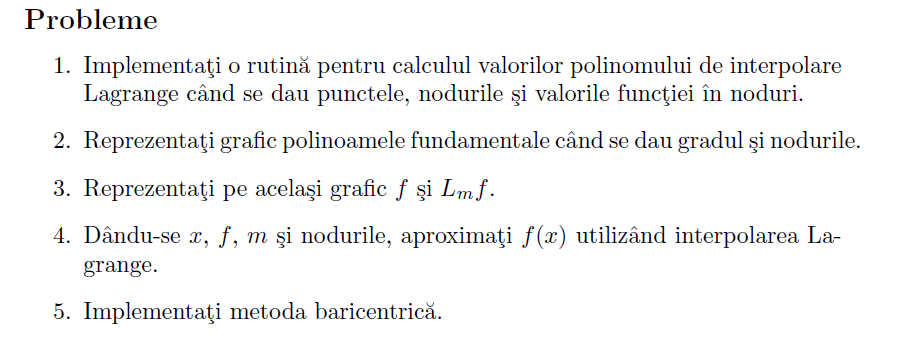Pr1

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];

lagrange(x,y,xx, false)

ans =   214.3644 -664.3068



x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = [1.25];
yy = lagrange(x,y,xx, false)

yy = 1.7550

Pr2

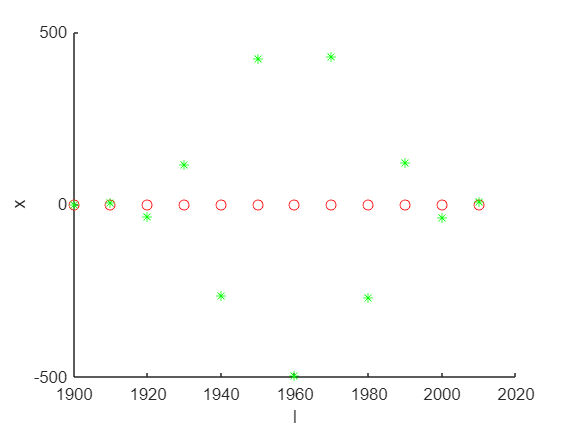

ans =   214.3644 -664.3068


x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];
lagrange(x,y,xx, true)

Pr3

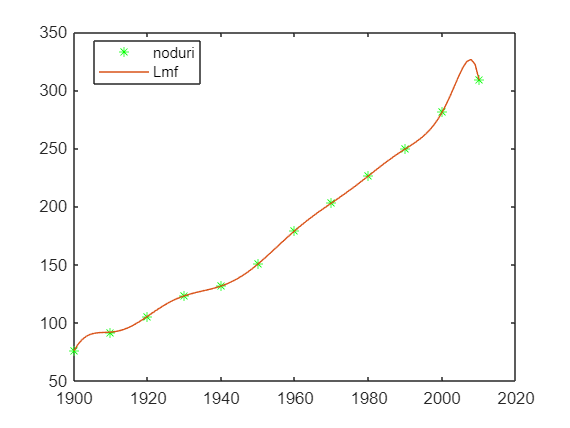

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = linspace(1900,2010,100);
yy = lagrange(x, y, xx, false);
plot(x,y,'g*', xx, yy)
legend('noduri','Lmf','Location', 'best')



x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = linspace(1,2,100);
yy = lagrange(x,y,xx, false)

yy =     1.0000    1.0204    1.0415    1.0632    1.0857    1.1089    1.1329    1.1576    1.1830    1.2093    1.2364    1.2644    1.2933    1.3230    1.3538    1.3855    1.4182    1.4520    1.4869    1.5230    1.5603    1.5987    1.6385    1.6796    1.7221    1.7661    1.8115    1.8585    1.9072    1.9575    2.0095    2.0634    2.1191    2.1768    2.2365    2.2983    2.3623    2.4285    2.4970    2.5679    2.6414    2.7174    2.7960    2.8774    2.9617    3.0489    3.1391    3.2324    3.3289    3.4288


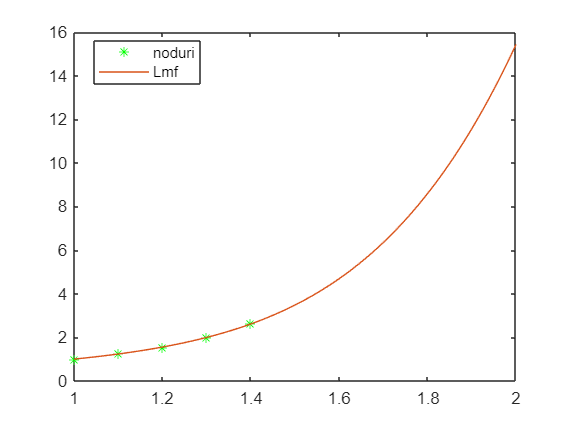

plot(x,y,'g*', xx, yy)
legend('noduri','Lmf','Location', 'best')

Pr4

syms t
lagrange(x,y,t)

$$ans = \frac{218524114084472875\,\left(5\,t-5\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{11}{10}\right)\,\left(t-\frac{13}{10}\right)}{281474976710656}-\frac{347249503194771625\,\left(10\,t-10\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{13}{10}\right)}{1688849860263936}+\frac{125\,\left(10\,t-11\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{13}{10}\right)}{3}+\frac{122521200672012375\,\left(\frac{5\,t}{2}-\frac{5}{2}\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{11}{10}\right)\,\left(t-\frac{13}{10}\right)}{281474976710656}-\frac{1122362066574539625\,\left(\frac{10\,t}{3}-\frac{10}{3}\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{11}{10}\right)}{1125899906842624}$$


x = [1 1.1 1.2 1.3 1.4];
y = [f(1) f(1.1) f(1.2) f(1.3) f(1.4)];
xx = [1.25];
yy = lagrange(x,y,t, false)

$$yy = \frac{218524114084472875\,\left(5\,t-5\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{11}{10}\right)\,\left(t-\frac{13}{10}\right)}{281474976710656}-\frac{347249503194771625\,\left(10\,t-10\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{13}{10}\right)}{1688849860263936}+\frac{125\,\left(10\,t-11\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{13}{10}\right)}{3}+\frac{122521200672012375\,\left(\frac{5\,t}{2}-\frac{5}{2}\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{11}{10}\right)\,\left(t-\frac{13}{10}\right)}{281474976710656}-\frac{1122362066574539625\,\left(\frac{10\,t}{3}-\frac{10}{3}\right)\,\left(t-\frac{6}{5}\right)\,\left(t-\frac{7}{5}\right)\,\left(t-\frac{11}{10}\right)}{1125899906842624}$$

Pr5

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
xx = [1975 2018];
c = barycentricweigths(x);
ff = barycentricInterpolation(x,y,xx,c)

ff =   214.3644 -664.3068


function y=f(x)
    y = exp(x.^2 -1);
end